# SIGDISC Project: EEG Signal Denoising with IIR and FIR filters

Submitter by SUPERLINK as their final project for SIGDISC: Signals Spectra, and Signal Processing.

clear
clf
 

## Set the signal-to-noise ratio for the awgn() command.

snrsetting = -15;

## Read the file containing the EEG signal

% Input data
data = edfread("Subject00_1.edf","SelectedSignals","EEG Fp1");
fs = 500;
data = table2array(data);
% seconds = 1;
% data = data(1:seconds);
data = vertcat(data{:});

% Time vector
t = 0 : 1/fs : (length(data) - 1)/fs;

## Add Gaussian noise to the EEG signal

% Add noise to EEG data
SNR = snrsetting;
data_gaussian = awgn(data, SNR);
% noise estimate
noise_estimate = randn(size(data))*std(data)/db2mag(snrsetting);

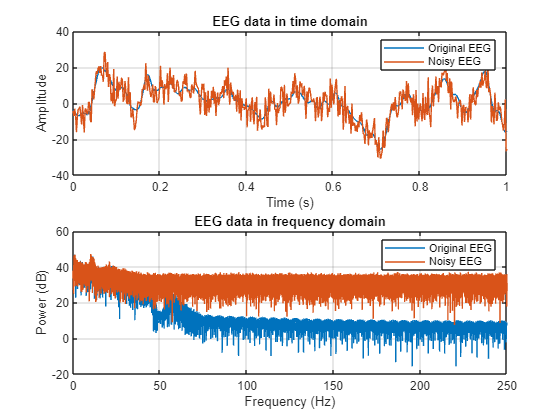

% Spectrum analysis of EEG data
n = length(data);
f = (0:n-1)*(fs/n);
powerFFTdata = pow2db(abs(fft(data)));
powerFFTdata_gaussian = pow2db(abs(fft(data_gaussian)));

% Plot the EEG data in time and frequency domains
clf
figure(1)
subplot(2, 1, 1)
plot(t, data)
hold on
plot(t, data_gaussian)
hold off
title("EEG data in time domain")
legend("Original EEG", "Noisy EEG")
xlabel("Time (s)")
ylabel("Amplitude")
xlim([0 1+1/fs])
grid on
subplot(2, 1, 2)
plot(f, powerFFTdata, f, powerFFTdata_gaussian)
title("EEG data in frequency domain")
legend("Original EEG", "Noisy EEG")
xlabel("Frequency (Hz)")
ylabel("Power (dB)")
xlim([0 fs/2])
grid on

## Design the low pass IIR filters (passband 70Hz, stopband 100Hz).

% Low pass IIR filter specifications
fpass = 50;
fstop = 80;
Wp = fpass/fs;
Ws = fstop/fs;
Rp = 3;
Rs = 15;

% Butterworth design
[N_butter, Wn_butter] = buttord(Wp, Ws, Rp, Rs);
[b_butter, a_butter] = butter(N_butter, Wn_butter, "low");
[mag_butter, w] = freqz(b_butter, a_butter, [], fs);

% Chebyshev Type 1 design
[N_cheb1, Wp_cheb1] = cheb1ord(Wp, Ws, Rp, Rs);
[b_cheb1, a_cheb1] = cheby1(N_cheb1, Rp, Wp_cheb1, "low");
[mag_cheb1, ~] = freqz(b_cheb1, a_cheb1, [], fs);

% Chebyshev Type 2 design
[N_cheb2, Ws_cheb2] = cheb2ord(Wp, Ws, Rp, Rs);
[b_cheb2, a_cheb2] = cheby2(N_cheb2, Rs, Ws_cheb2, "low");
[mag_cheb2, ~] = freqz(b_cheb2, a_cheb2, [], fs);

% Elliptic design
[N_ellip, Wn_ellip] = ellipord(80/fs, 120/fs, Rp, 30);
[b_ellip, a_ellip] = ellip(N_ellip, Rp, Rs, Wp, "low");
[mag_ellip, ~] = freqz(b_ellip, a_ellip, [], fs);

## Design the low pass FIR filters (Cutoff between pass and stop frequencies in IIR filter design)

% Low pass FIR filter specifications
N = ceil((fs/(fstop-fpass))*(Rs/22))

N = 12

Wn = mean([Wp Ws]);

% FIR filter with Bartlett window
b_bartlett = fir1(N, Wn, 'low', bartlett(N+1));
[mag_bartlett, ~] = freqz(b_bartlett, 1, [], fs);

% FIR filter with Hamming window
b_hamming = fir1(N, Wn, 'low', hamming(N+1));
[mag_hamming, ~] = freqz(b_hamming, 1, [], fs);

% FIR filter with Hanning window
b_hanning = fir1(N, Wn, 'low', hanning(N+1));
[mag_hanning, ~] = freqz(b_hanning, 1, [], fs);

% FIR filter with Blackman window
b_blackman = fir1(N, Wn, 'low', blackman(N+1));
[mag_blackman, ~] = freqz(b_blackman, 1, [], fs);

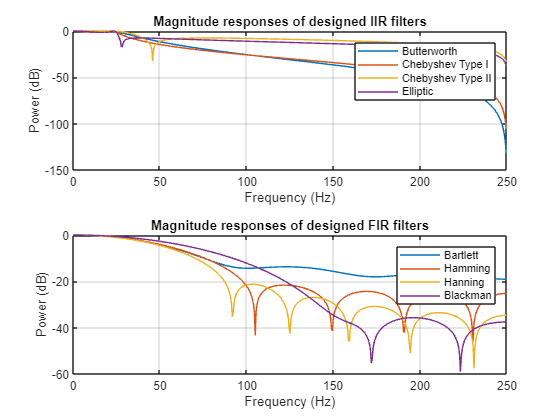

% IIR magnitude responses
clf
figure(2)
tiledlayout(2, 1)
nexttile
plot(w, pow2db(abs(mag_butter)), ...
     w, pow2db(abs(mag_cheb1)), ...
     w, pow2db(abs(mag_cheb2)), ...
     w, pow2db(abs(mag_ellip)))
title("Magnitude responses of designed IIR filters")
legend("Butterworth", "Chebyshev Type I", "Chebyshev Type II", "Elliptic");
xlabel("Frequency (Hz)")
ylabel("Power (dB)")
xlim([0 fs/2])
grid on
nexttile
% FIR magnitude responses
plot(w, pow2db(abs(mag_bartlett)), ...
     w, pow2db(abs(mag_hamming)), ...
     w, pow2db(abs(mag_hanning)), ...
     w, pow2db(abs(mag_blackman)))
title("Magnitude responses of designed FIR filters")
legend("Bartlett", "Hamming", "Hanning", "Blackman");
xlabel("Frequency (Hz)")
ylabel("Power (dB)")
xlim([0 fs/2])
grid on

## Filter the noisy EEG signal with the designed IIR and FIR filters.

data_gaussian = awgn(data, SNR);

% IIR filtering
butter_EEG = filtfilt(b_butter, a_butter, data_gaussian);
cheb1_EEG = filtfilt(b_cheb1, a_cheb1, data_gaussian);
cheb2_EEG = filtfilt(b_cheb2, a_cheb2, data_gaussian);
ellip_EEG = filtfilt(b_ellip, a_ellip, data_gaussian);

% FIR filtering
bartlett_EEG = filtfilt(b_bartlett, 1, data_gaussian);
hamming_EEG = filtfilt(b_hamming, 1, data_gaussian);
hanning_EEG = filtfilt(b_hanning, 1, data_gaussian);
blackman_EEG = filtfilt(b_blackman, 1, data_gaussian);

% FFT power of filtered signals
FFT_butter = pow2db(abs(fft(butter_EEG)));
FFT_cheb1 = pow2db(abs(fft(cheb1_EEG)));
FFT_cheb2 = pow2db(abs(fft(cheb2_EEG)));
FFT_ellip = pow2db(abs(fft(ellip_EEG)));
FFT_bartlett = pow2db(abs(fft(bartlett_EEG)));
FFT_hamming = pow2db(abs(fft(hamming_EEG)));
FFT_hanning = pow2db(abs(fft(hanning_EEG)));
FFT_blackman = pow2db(abs(fft(blackman_EEG)));

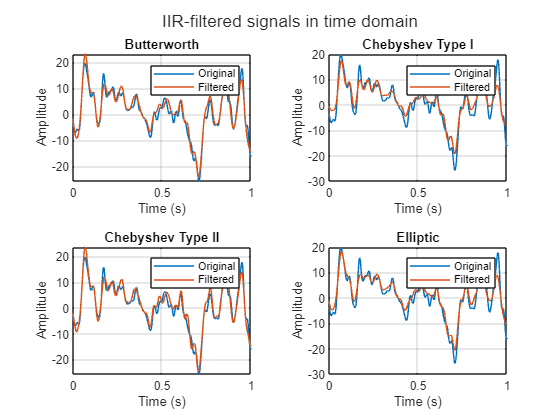

% IIR-filtered signals in time domain
clf
figure(4)
tiledlayout(2, 2)
sgtitle("IIR-filtered signals in time domain")
nexttile
plot(t, data, t, butter_EEG)
title("Butterworth")
legend("Original", "Filtered")
xlabel("Time (s)")
ylabel("Amplitude")
xlim([0 1+1/fs])
grid on
nexttile
plot(t, data, t, cheb1_EEG)
title("Chebyshev Type I")
legend("Original", "Filtered")
xlabel("Time (s)")
ylabel("Amplitude")
xlim([0 1+1/fs])
grid on
nexttile
plot(t, data, t, cheb2_EEG)
title("Chebyshev Type II")
legend("Original", "Filtered")
xlabel("Time (s)")
ylabel("Amplitude")
xlim([0 1+1/fs])
grid on
nexttile
plot(t, data, t, ellip_EEG)
title("Elliptic")
legend("Original", "Filtered")
xlabel("Time (s)")
ylabel("Amplitude")
xlim([0 1+1/fs])
grid on

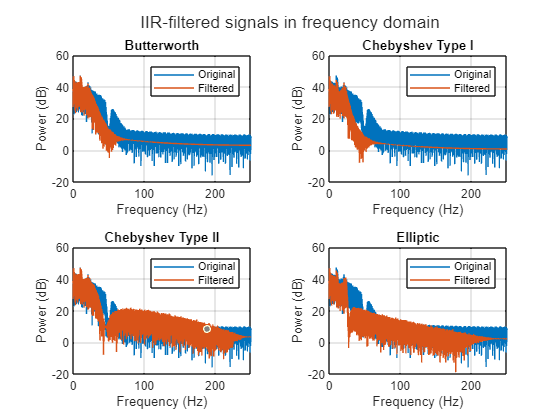


% IIR-filtered signals in frequency domain
clf
figure(5)
tiledlayout(2, 2)
sgtitle("IIR-filtered signals in frequency domain")
nexttile
plot(f, powerFFTdata, f, FFT_butter)
title("Butterworth")
legend("Original", "Filtered")
xlabel("Frequency (Hz)")
ylabel("Power (dB)")
xlim([0 fs/2])
grid on
nexttile
plot(f, powerFFTdata, f, FFT_cheb1)
title("Chebyshev Type I")
legend("Original", "Filtered")
xlabel("Frequency (Hz)")
ylabel("Power (dB)")
xlim([0 fs/2])
grid on
nexttile
plot(f, powerFFTdata, f, FFT_cheb2)
title("Chebyshev Type II")
legend("Original", "Filtered")
xlabel("Frequency (Hz)")
ylabel("Power (dB)")
xlim([0 fs/2])
grid on
nexttile
plot(f, powerFFTdata, f, FFT_ellip)
title("Elliptic")
legend("Original", "Filtered")
xlabel("Frequency (Hz)")
ylabel("Power (dB)")
xlim([0 fs/2])
grid on

## Display filter results in both time and frequency domain.

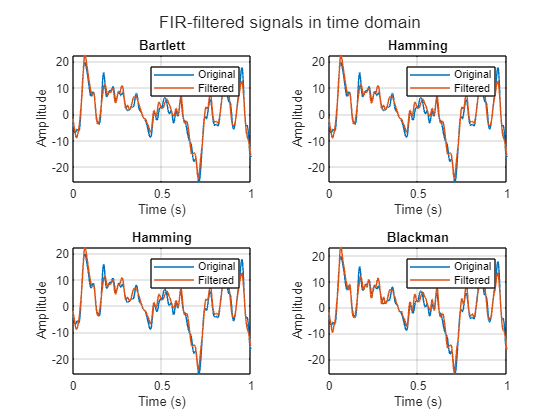

% FIR-filtered signals in time domain
clf
figure(6)
tiledlayout(2, 2)
sgtitle("FIR-filtered signals in time domain")
nexttile
plot(t, data, t, bartlett_EEG)
title("Bartlett")
legend("Original", "Filtered")
xlabel("Time (s)")
ylabel("Amplitude")
xlim([0 1+1/fs])
grid on
nexttile
plot(t, data, t, hamming_EEG)
title("Hamming")
legend("Original", "Filtered")
xlabel("Time (s)")
ylabel("Amplitude")
xlim([0 1+1/fs])
grid on
nexttile
plot(t, data, t, hanning_EEG)
title("Hamming")
legend("Original", "Filtered")
xlabel("Time (s)")
ylabel("Amplitude")
xlim([0 1+1/fs])
grid on
nexttile
plot(t, data, t, blackman_EEG)
title("Blackman")
legend("Original", "Filtered")
xlabel("Time (s)")
ylabel("Amplitude")
xlim([0 1+1/fs])
grid on

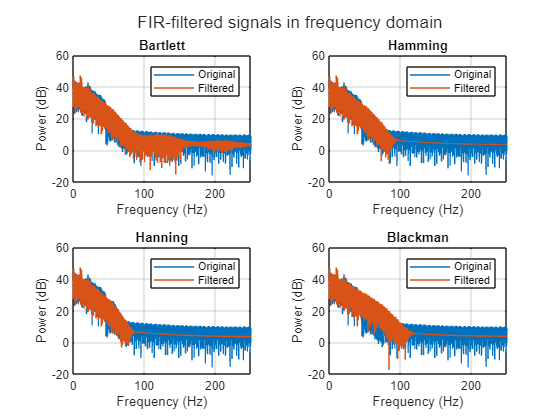


% FIR-filtered signals in frequency domain
clf
figure(7)
tiledlayout(2, 2)
sgtitle("FIR-filtered signals in frequency domain")
nexttile
plot(f, powerFFTdata, f, FFT_bartlett)
title("Bartlett")
legend("Original", "Filtered")
xlabel("Frequency (Hz)")
ylabel("Power (dB)")
xlim([0 fs/2])
grid on
nexttile
plot(f, powerFFTdata, f, FFT_hamming)
title("Hamming")
legend("Original", "Filtered")
xlabel("Frequency (Hz)")
ylabel("Power (dB)")
xlim([0 fs/2])
grid on
nexttile
plot(f, powerFFTdata, f, FFT_hanning)
title("Hanning")
legend("Original", "Filtered")
xlabel("Frequency (Hz)")
ylabel("Power (dB)")
xlim([0 fs/2])
grid on
nexttile
plot(f, powerFFTdata, f, FFT_blackman)
title("Blackman")
legend("Original", "Filtered")
xlabel("Frequency (Hz)")
ylabel("Power (dB)")
xlim([0 fs/2])
grid on

data_gaussian = awgn(data, SNR);

% IIR filtering
butter_EEG = filtfilt(b_butter, a_butter, data_gaussian);
cheb1_EEG = filtfilt(b_cheb1, a_cheb1, data_gaussian);
cheb2_EEG = filtfilt(b_cheb2, a_cheb2, data_gaussian);
ellip_EEG = filtfilt(b_ellip, a_ellip, data_gaussian);

% FIR filtering
bartlett_EEG = filtfilt(b_bartlett, 1, data_gaussian);
hamming_EEG = filtfilt(b_hamming, 1, data_gaussian);
hanning_EEG = filtfilt(b_hanning, 1, data_gaussian);
blackman_EEG = filtfilt(b_blackman, 1, data_gaussian);

## Signal-to-noise ratio improvement

% SNR value used in awgn()
awgnSNR = snrsetting;

% Basis value for SNR
db_dataSNR = snr(data, noise_estimate);

% SNR of noisy EEF data
db_SNR_gaussian = snr(data_gaussian, noise_estimate)

db_SNR_gaussian = -13.5877


% SNR of IIR-filtered data
db_SNR_butter = snr(butter_EEG, noise_estimate);
db_SNR_cheb1 = snr(cheb1_EEG, noise_estimate);
db_SNR_cheb2 = snr(cheb2_EEG, noise_estimate);
db_SNR_ellip = snr(ellip_EEG, noise_estimate);

% SNR of FIR-filtered data
db_SNR_bartlett = snr(bartlett_EEG, noise_estimate);
db_SNR_hamming = snr(hamming_EEG, noise_estimate);
db_SNR_hanning = snr(hanning_EEG, noise_estimate);
db_SNR_blackman = snr(blackman_EEG, noise_estimate);

## Mean-squared error

% MSE between original data and itself
MSE_data = immse(data, data);

% MSE between original data and noisy data
MSE_gaussian = immse(data_gaussian, data);

% MSE between original data and IIR filter results
MSE_butter = immse(butter_EEG, data);
MSE_cheb1 = immse(cheb1_EEG, data);
MSE_cheb2 = immse(cheb2_EEG, data);
MSE_ellip = immse(ellip_EEG, data);

% MSE between original data and FIR filter results
MSE_bartlett = immse(bartlett_EEG, data);
MSE_hamming = immse(hamming_EEG, data);
MSE_hanning = immse(hanning_EEG, data);
MSE_blackman = immse(blackman_EEG, data);

## Root mean square error

% RMSE between original data and itself
RMS_data = rmse(data, data);

% RMSE between original data and noisy data
RMS_gaussian = rmse(data_gaussian, data);

% RMSE between original data and IIR filter results
RMS_butter = rmse(butter_EEG, data);
RMS_cheb1 = rmse(cheb1_EEG, data);
RMS_cheb2 = rmse(cheb2_EEG, data);
RMS_ellip = rmse(ellip_EEG, data);

% RMSE between original data and FIR filter results
RMS_bartlett = rmse(bartlett_EEG, data);
RMS_hamming = rmse(hamming_EEG, data);
RMS_hanning = rmse(hanning_EEG, data);
RMS_blackman = rmse(blackman_EEG, data);

% Form the table of data

Signals = ["Original EEG"; ...
           "Noisy EEG"; ...
           "Butterworth"; ...
           "Chebyshev Type I"; ...
           "Chebyshev Type II"; ...
           "Elliptic"; ...
           "Bartlett"; ...
           "Hamming"; ...
           "Hanning"; ...
           "Blackman"];

SNR_data = [db_dataSNR; db_SNR_gaussian ; db_SNR_butter ; db_SNR_cheb1 ;...
    db_SNR_cheb2 ; db_SNR_ellip ; db_SNR_bartlett ; db_SNR_hamming ; ...
    db_SNR_hanning ; db_SNR_blackman];

SNR_improvement = -SNR_data;
SNR_improvement(Signals == "Noisy EEG") = 0;

MSE = [MSE_data ; MSE_gaussian ; MSE_butter ; MSE_cheb1 ;...
    MSE_cheb2 ; MSE_ellip ; MSE_bartlett ; MSE_hamming ; ...
    MSE_hanning ; MSE_blackman];

RMSE = [RMS_data ; RMS_gaussian ; RMS_butter ; RMS_cheb1 ;...
    RMS_cheb2 ; RMS_ellip ; RMS_bartlett ; RMS_hamming ; ...
    RMS_hanning ; RMS_blackman];

analysis_data = table(Signals, SNR_improvement, MSE, RMSE)

analysis_data = 10×4 table
          Signals          SNR_improvement     MSE       RMSE 
    ___________________    _______________    ______    ______
    "Original EEG"             14.983              0         0
    "Noisy EEG"                     0         31.781    5.6375
    "Butterworth"              15.029         4.5891    2.1422
    "Chebyshev Type I"          17.46         13.451    3.6676
    "Chebyshev Type II"        14.928         4.2955    2.0726
    "Elliptic"                 16.956         10.525    3.2442
    "Bartlett"                 15.453         4.4478     2.109
    "Hamming"                   15.45         4.4469    2.1088
    "Hanning"                  15.493         4.5105    2.1238
    "Blackman"                 15.234         4.3896    2.0951


save("session.mat", "analysis_data")